# **Script illustrating how to use Watson's (2014) formulas for cone mosaics that employ the ISETBio cone density function**

*This script illustrates how we can use formulas from the Watson (2014) paper with mosaics that employ the ISETBio cone density, which has a significantly higher foveal cone density that the cone density used in Watson's 2014 model.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2020*

# **Step 1.** Reproduce Watson's figure

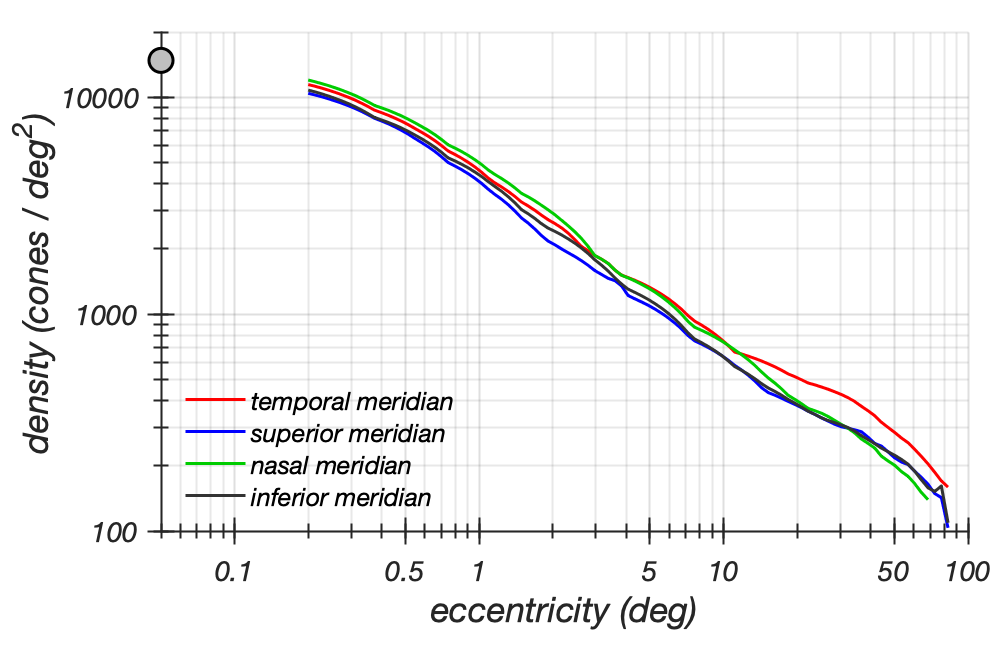

% Instantiate the Watson RGC model
obj = WatsonRGCModel('instantiatePlotLab', true); 

% Reproduce that figure using the static method 
% unitTestFigure1() of the @WatsonRGCModel Matlab class
WatsonRGCModel.unitTestFigure1();

The original figure (digitized from Watson's paper) is show below.

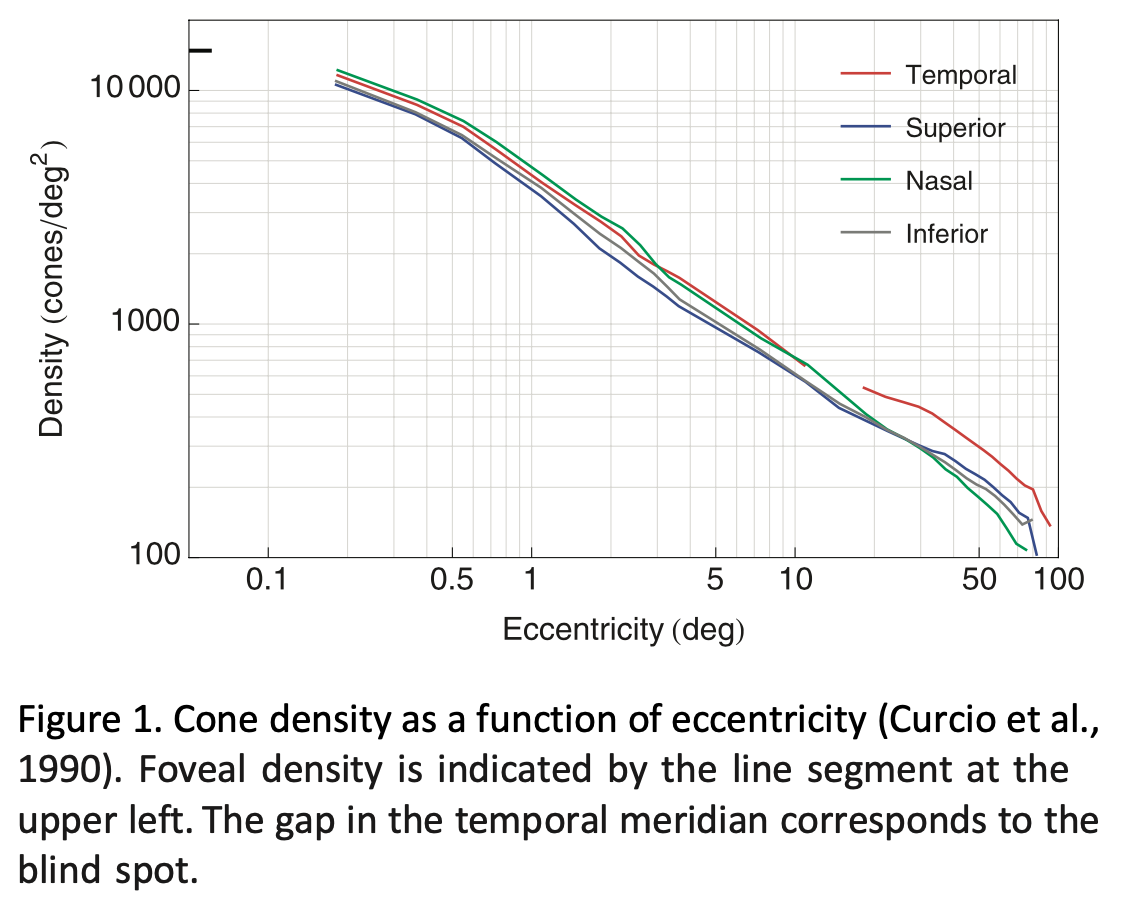

# **Step 2.** Illustrating the problem of using Watson's formulas with the ISETBio cone density

The peak density in Watson's model (196,870 cones / mm^2) is significantly lower from the peak density in ISETBio, which is 250,000 cones/mm^2, and which corresponds to a 2 micron cone separation, IN A RECTANGULAR grid. Also note that the conversion from degs to microns in Watson's paper differs from 300, even for foveal eccentricities.

% Watson's microns/degree conversion factor (different from 300 in ISETBio)
micronsPerDegreeFovealWatson = obj.rhoDegsToMMs(0.001)*1000

micronsPerDegreeFovealWatson = 0.2680

% Watson's peak cone density per deg^2
peakConeDensityPerDeg2Watson = obj.dc0

peakConeDensityPerDeg2Watson = 1.4805e+04

% Convert to peak density per mm^2 using Watson's retinal area mm^2 -> deg^2 conversion factor (alpha),
% which is a function of eccentricity in degs (Equation A7)
peakConeDensityPerMM2Watson = peakConeDensityPerDeg2Watson  * 1/obj.alpha(0)

peakConeDensityPerMM2Watson = 1.9687e+05

% ISETBio peak cone density is 250,000
peakConeDensityPerMM2ISETBio = 250000

peakConeDensityPerMM2ISETBio = 250000

% Compute corresponding foveal cone spacings in a hex lattice
fovealConeSpacingMicronsISETBio = obj.spacingFromDensity(peakConeDensityPerMM2ISETBio )*1000

fovealConeSpacingMicronsISETBio = 2.1491

fovealConeSpacingMicrosWatson = obj.spacingFromDensity(peakConeDensityPerMM2Watson)*1000

fovealConeSpacingMicrosWatson = 2.4218

This discrepancy in foveal cone density generates a problem if we want to use the ISETBio cone density with Watson's formula for RGC density. This problem is illustrated below in which we plot the ratio of midget RGCs to cones. Not that the ratio dips below 2.0 at eccentricities below 0.18 degs. 

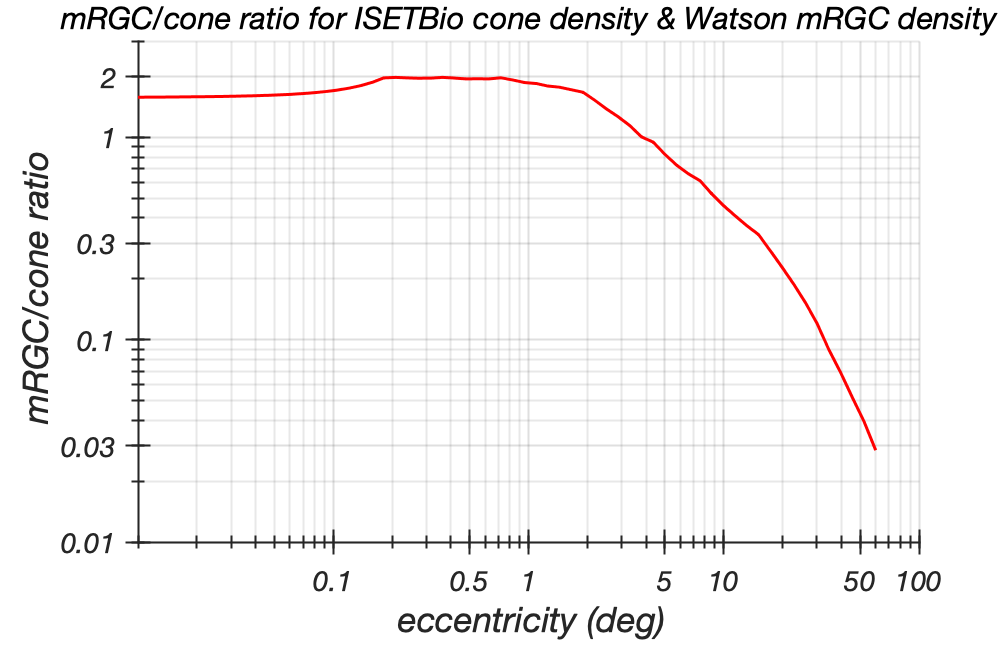

eccentricities = logspace(log10(0.01), log10(60), 64); 
densityUnits = 'deg^2'; eccUnits = 'deg';
rightEyeVisualFieldMeridianName = 'superior meridian';

% Extract cone density without correction to match Watson's (this is the ISETBio density)
[~, coneDensityISETBio] = obj.coneRFSpacingAndDensityAlongMeridian(eccentricities, ...
        rightEyeVisualFieldMeridianName, eccUnits, densityUnits, ...
        'correctForMismatchInFovealConeDensityBetweenWatsonAndISETBio', false);

% Compute midget RGC density using Watson's formula
[~, mRGCRFDensityWatson] = obj.mRGCRFSpacingAndDensityAlongMeridian(eccentricities, ...
        rightEyeVisualFieldMeridianName, eccUnits, densityUnits);

% Plot the ratio of midget RGCs to cones
figure(1); clf;
plot(eccentricities, mRGCRFDensityWatson./coneDensityISETBio);
set(gca, 'XScale', 'log', 'YScale', 'log', 'YLim', [0.01 3], 'Box', 'off', ...
    'XTick', [0.1 0.5 1 5 10 50 100], 'YTick', [0.01 0.03 0.1 0.3 1 2]);
xlabel('\it eccentricity (deg)'); ylabel('\it mRGC/cone ratio');
title('mRGC/cone ratio for ISETBio cone density & Watson mRGC density')

# **Step 3.** To use Watson's formulas we have to fix this discrepancy in cone densities.

We do this by setting the  'correctForMismatchInFovealConeDensityBetweenWatsonAndISETBio' flag to true, when requesting cone densities from the @WatsonRGCModel. 

Doing so adjusts the ISETBio density data to match the Watson density data and results in correct usage of the Watson's formulas  as illustrated below.

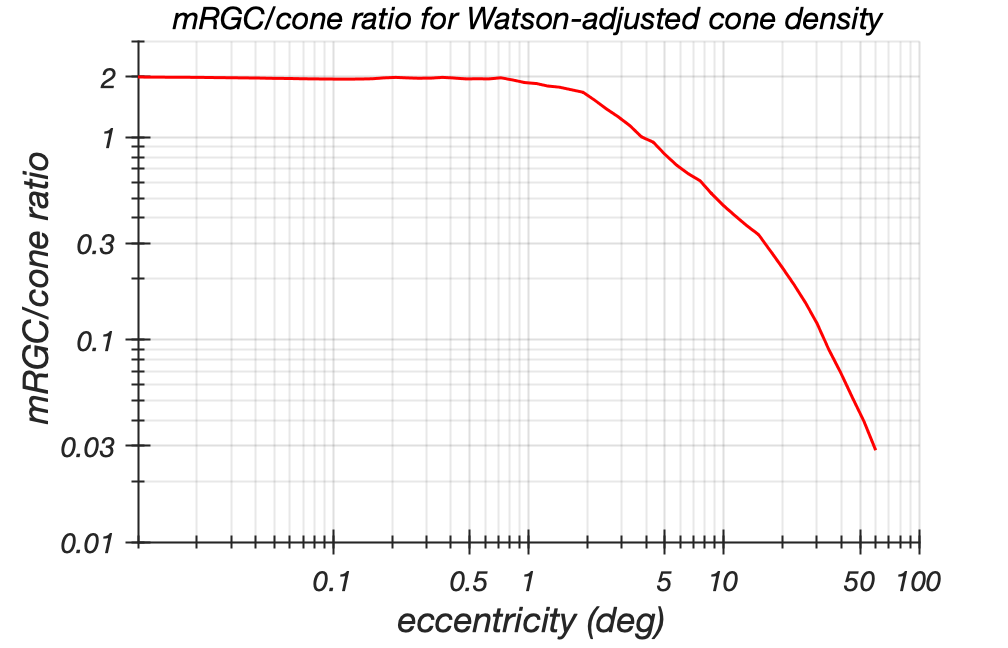

eccentricities = logspace(log10(0.01), log10(60), 64); 
densityUnits = 'deg^2'; eccUnits = 'deg';
rightEyeVisualFieldMeridianName = 'superior meridian';

% Extract cone density with correction for mismatch (this is the Watson density)
[~, coneDensityWatson] = obj.coneRFSpacingAndDensityAlongMeridian(eccentricities, ...
        rightEyeVisualFieldMeridianName, eccUnits, densityUnits, ...
        'correctForMismatchInFovealConeDensityBetweenWatsonAndISETBio', true);
    
% Compute midget RGC density using Watson's formula
[~, mRGCRFDensity] = obj.mRGCRFSpacingAndDensityAlongMeridian(eccentricities, ...
        rightEyeVisualFieldMeridianName, eccUnits, densityUnits);

% Compute midget-to-cone ratio
midgetToConeRatio = mRGCRFDensity./coneDensityWatson;

% Plot the ratio of midget RGCs to cones
figure(1); clf;
plot(eccentricities, midgetToConeRatio);
set(gca, 'XScale', 'log', 'YScale', 'log', 'YLim', [0.01 3],'Box', 'off', ...
    'XTick', [0.1 0.5 1 5 10 50 100], 'YTick', [0.01 0.03 0.1 0.3 1 2]);
xlabel('\it eccentricity (deg)'); ylabel('\it mRGC/cone ratio');
title('mRGC/cone ratio for Watson-adjusted cone density')

# **Step 4.** Deriving midget cone densities appropriate for ISETBio's cone density. 

Having derived the correct midget to cone ratio function, we can now derive midget densities appropriate for ISETBio's cone density.

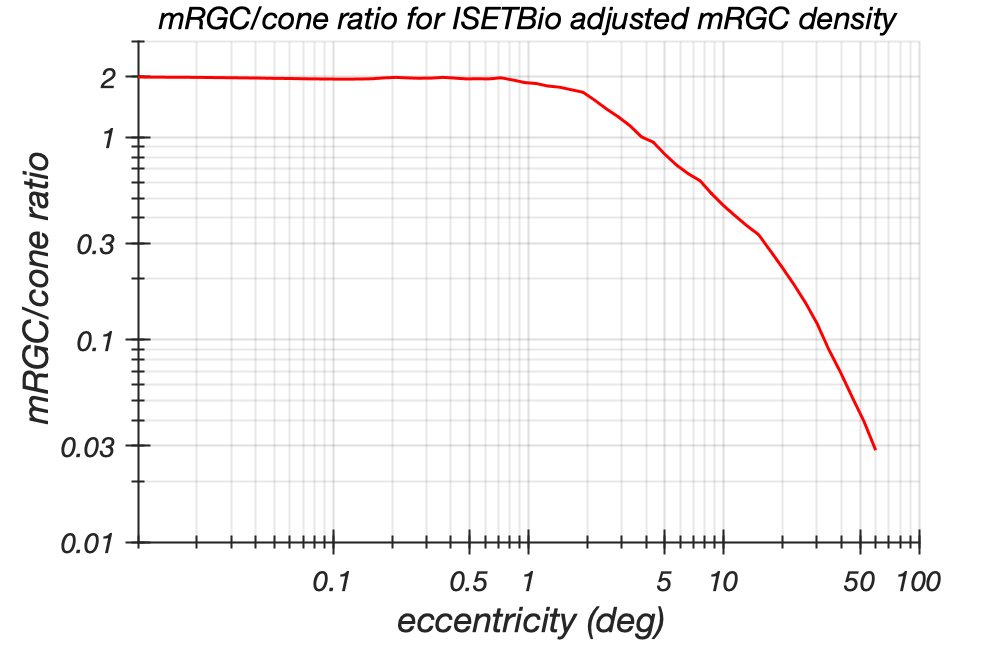

eccentricities = logspace(log10(0.01), log10(60), 64); 
densityUnits = 'deg^2'; eccUnits = 'deg';
rightEyeVisualFieldMeridianName = 'superior meridian';

% Extract cone density without correction to match Watson's (this is the ISETBio density)
[~, coneDensityISETBio] = obj.coneRFSpacingAndDensityAlongMeridian(eccentricities, ...
        rightEyeVisualFieldMeridianName, eccUnits, densityUnits, ...
        'correctForMismatchInFovealConeDensityBetweenWatsonAndISETBio', false);
    
% Compute midget RGC density appropriate for ISETBio cone density
mRGCRFDensityISETBio = coneDensityISETBio .* midgetToConeRatio;

% Plot the ratio of midget RGCs to cones
figure(1); clf;
plot(eccentricities, mRGCRFDensityISETBio./coneDensityISETBio);
set(gca, 'XScale', 'log', 'YScale', 'log', 'YLim', [0.01 3],'Box', 'off', ...
    'XTick', [0.1 0.5 1 5 10 50 100], 'YTick', [0.01 0.03 0.1 0.3 1 2]);
xlabel('\it eccentricity (deg)'); ylabel('\it mRGC/cone ratio');
title('mRGC/cone ratio for ISETBio adjusted mRGC density');

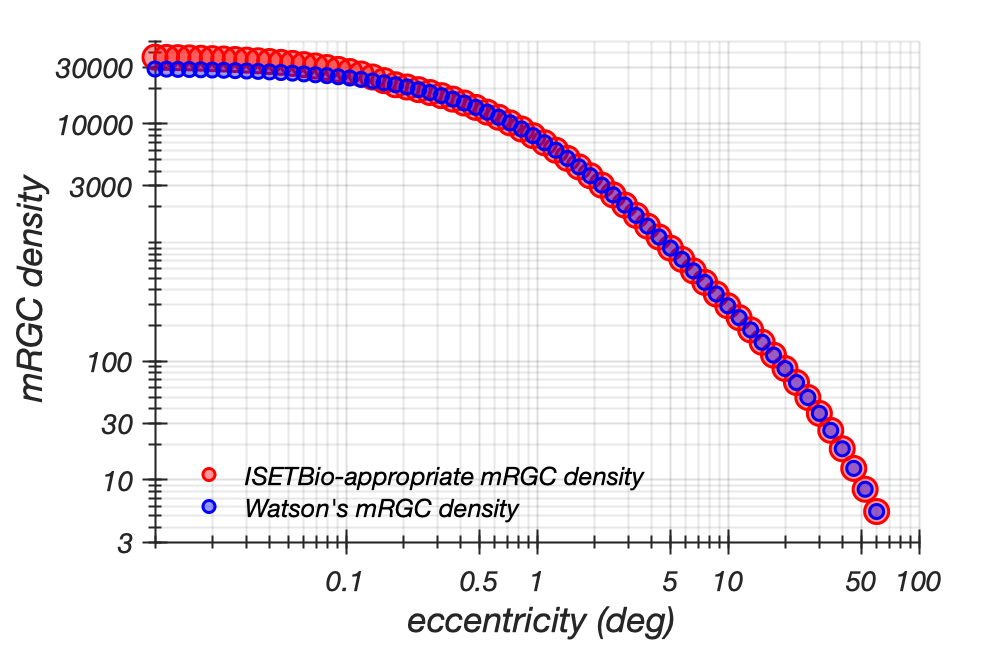


% Plot the original Watson midget RGC density and the ISETBio-adjusted one
hfig = figure(1); clf;
scatter(eccentricities, mRGCRFDensityISETBio); hold on;
scatter(eccentricities, mRGCRFDensity, 49);
set(gca, 'XScale', 'log', 'YScale', 'log', 'YLim', [3 50000], ...
    'XTick', [0.1 0.5 1 5 10 50 100], 'YTick', [1 3 10 30 100 3000 10000 30000]);
xlabel('\it eccentricity (deg)'); ylabel('\it mRGC density');
legend({'ISETBio-appropriate mRGC density', 'Watson''s mRGC density'})